Space Mech Project #1 Code:

By: Kaleb Nails & Joshuwa May

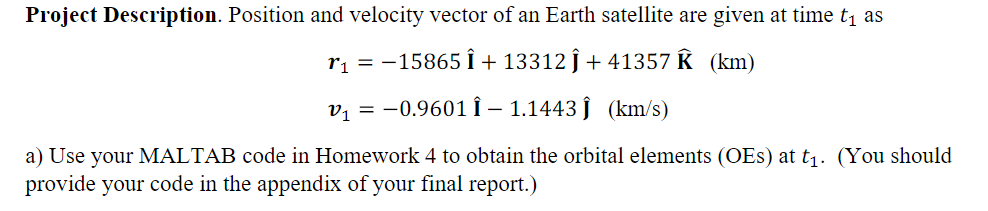

clear;clc;close
mu_earth = 398600;

%Take the given vectors and plug them into your OEtoRv equations
r_vec1 = [-15865,13312,41357];
v_vec1 = [-.9601,-1.1443,0];
[a,e_mag,f,inclination,Omega,arg_periapsis,e_Vec] = RVtoOE(r_vec1,v_vec1);

				RVtoOE
Semi Major Axis: 26565.2768 km 
Eccentricity: 0.7411 
Inclination: 63.4000 deg 
Longitude of Ascending Node: 50.0024 deg
Argument of Periapsis: 269.9990 deg
True Anomoly: 180.0003 deg


%NOTE:
%This considers the circular case
if e_mag == 0

    %First obtain period and your N
    period = 2*pi*sqrt(a^3/mu_earth);
    N = 2*pi/period;
    
    %We consider that f has a constant rate of change in a cirular orbit
    percentage = f/360; 

    %We also do not need to calculate eccentric anomoly, and for sake of it
    %being reference later in the code we can just set it to zero for now
    Eccentric_annomoly = 0.00;

    t1 = Period*Percentage;


Next using the following Equations you can solve the needed variables for an hyperbolic orbit

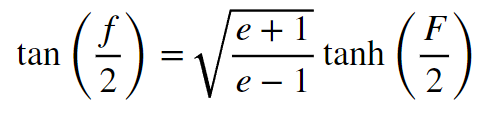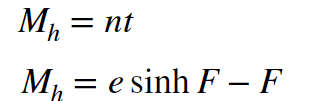

%This consider the hyperbolic case    

%consider f=0, as t=0;
elseif e_mag >1

    %First obtain period and your N
    period = 2*pi*sqrt(a^3/mu_earth);
    N = 2*pi/period;


    %Then use Equations to solve for Eccentric anonomly
    syms F
    
    hyperbolic_tan_EQ = tan(f/2*(pi/180)) == sqrt((e_mag+1)/(e_mag-1))*tanh(F/2);
    F = solve(hypberbolic_tan_EQ,F);

   %forces it to be CCW
    if F < 0
        F = F + 2*pi;
    end
    Eccentric_annomoly = F;

    Mh = e_mag*sinh(F)-F;
    t1 = Mh/N;


Next using the following Equations you can solve the needed variables for an elliptical orbit

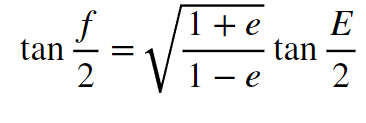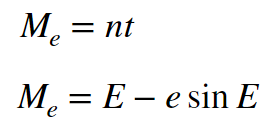

%This considers the elliptical case
elseif (e_mag > 0) && (e_mag < 1)
    %First obtain period and your N
    period = 2*pi*sqrt(a^3/mu_earth);
    N = 2*pi/period;
    
    %Then use Equation to solve for Eccentric anonomly
    E = 2*atan(sqrt((1-e_mag)/(1+e_mag))*tand(f/2));

    %forces it to be CCW
    if E < 0
        E = E + 2*pi;
    end

    Eccentric_annomoly = E;
    Me = E - sin(E);
    t1 = Me/N;
end

fprintf('Time1 (t1) is: %.4f seconds',t1);

Time1 (t1) is: 21545.4780 seconds

fprintf('The Eccentric annomaly is: %.4f Radians',Eccentric_annomoly);

The Eccentric annomaly is: 3.1416 Radians

These can be found with these fundamental equations:

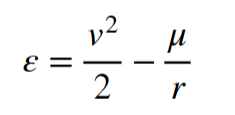


%To obtain specific energy and our angular moment vector and magnitude use
%the funtions below.
specificE = RV_to_specific_energy(r_vec1,v_vec1);

the specific energy ( ε ) is: -7.5023 km^2/s^2

[h_vec,h_mag]= RV_to_h(r_vec1,v_vec1);

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)


%Determine the orbits shape using ecentricity
if e_mag == 0
    fprintf('the orbit is a circle')

%This considers the hyperbolic case
elseif e_mag >1
    fprintf('the orbit is a hyperbola')

%This considers the elliptical case
elseif (e_mag > 0) && (e_mag < 1)
    fprintf('the orbit is elliptical')

%This consider the parabolic case    
elseif e_mag == 1
    fprintf('the orbit is parabolic')

end

the orbit is elliptical

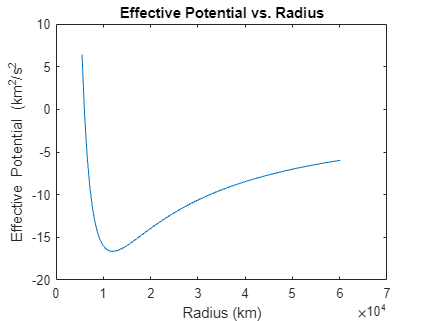

%Createa a range or radius from the radius of the earth to a little further
%than apoapsis. %Note this is an elipse, and this equation will have issues
%with finding the apoapsis of any od shape such as a parabola and
%hyperbola, but this will work for circles and ellipses. which is the
%current use case.
ra = -mu_earth/(2*specificE)*(1+sqrt(1+2*specificE*h_mag^2/mu_earth^2));

r_range = linspace(5500,ra*1.3,100); %Note: the 1.3 is for scaping reasons

%Use the given equation for Ueff(r)
Ueff = .5*h_mag^2./r_range.^2-mu_earth./r_range;

plot(r_range,Ueff);

% Label the axes
xlabel('Radius (km)');
ylabel('Effective Potential (km^2/s^2');

% Title for the plot (if needed)
title('Effective Potential vs. Radius');

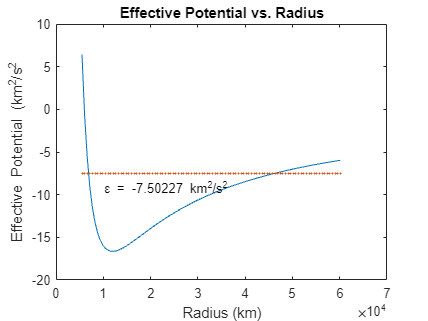

hold on
plot(r_range,specificE * ones(size(r_range)),'o', 'MarkerSize', 1);


labely = specificE*1.25;  
epsilon_symbol = char(949);
label_text = sprintf('%s = %g km^2/s^2', epsilon_symbol,specificE);  
text(10000, labely, label_text, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');
hold off

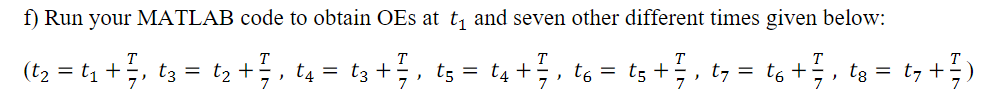

t_list = [0,t1];

%start Eccentric annomoly at zero, because we start at periapsis
true_annomoly_table = [0,f];

%Use a for loop to iterate through the times
t_old = t1;
for for_loop_counter=2:8
    t_now = t_old + period/7;
    t_old = t_now;
    Me_new = N*t_now;
    fprintf('t%.0f: %.2f (s)', for_loop_counter, t_now);

    %USE NETWONIAN METHOD TO GET THE M OR ELLIPSE, and the other method
    [~,true_annomoly_temp] = newtonian_method(e_mag,Me_new); 
    true_annomoly_temp = true_annomoly_temp*180/pi; %converted to radians

    %This is a different way to get eccentric annomoly and just validates
    %the previous newtons method.
    NOTNEWTON_method(e_mag,Me_new);

    %Now append your new time & annomoly values to the end of your lists
    t_list = cat(2,t_list,t_old);
    true_annomoly_table = cat(2,true_annomoly_table,true_annomoly_temp);

end

t2: 27701.28 (s)

Ecentricity annomaly [E2]: 210.1213 deg
true annomaly [E2]: 191.8481 deg




 OTHER METHOD Eccentric anomoly: 210.1213 deg
OTHER METHOD true annomaly [E2]: 191.8481 deg



t3: 33857.08 (s)

Ecentricity annomaly [E2]: 244.5253 deg
true annomaly [E2]: 207.3625 deg




 OTHER METHOD Eccentric anomoly: 244.5253 deg
OTHER METHOD true annomaly [E2]: 207.3625 deg



t4: 40012.89 (s)

Ecentricity annomaly [E2]: 296.1823 deg
true annomaly [E2]: 243.5408 deg




 OTHER METHOD Eccentric anomoly: 296.1823 deg
OTHER METHOD true annomaly [E2]: 243.5408 deg



t5: 46168.69 (s)

Ecentricity annomaly [E2]: 423.8219 deg
true annomaly [E2]: 116.4634 deg




 OTHER METHOD Eccentric anomoly: 423.8219 deg
OTHER METHOD true annomaly [E2]: 116.4634 deg



t6: 52324.49 (s)

Ecentricity annomaly [E2]: 475.4769 deg
true annomaly [E2]: 152.6386 deg




 OTHER METHOD Eccentric anomoly: 475.4769 deg
OTHER METHOD true annomaly [E2]: 152.6386 deg



t7: 58480.29 (s)

Ecentricity annomaly [E2]: 509.8804 deg
true annomaly [E2]: 168.1526 deg




 OTHER METHOD Eccentric anomoly: 509.8804 deg
OTHER METHOD true annomaly [E2]: 168.1526 deg



t8: 64636.10 (s)

Ecentricity annomaly [E2]: 540.0008 deg
true annomaly [E2]: 180.0003 deg




 OTHER METHOD Eccentric anomoly: 540.0008 deg
OTHER METHOD true annomaly [E2]: 180.0003 deg




%disp(t_list)
%disp(Eccentric_annomoly_table)


It is important to note that the only OE that can change in this case where we are not considering pertabations is the true anomoly,

thus the rest of the values can remain the same.

**ASK IF WE HAVE TO RECALCULATE OR IF WE CAN JUST SAY ITS CONSTANT!!!!!!!!!!!!!!!!!!!!!!!!**

%Generate the rows of the constant OE's
Ecentricity_table = e_mag * ones(1, length(t_list));
Semi_Major_axis_table = a * ones(1, length(t_list));
inclination_table = inclination * ones(1, length(t_list));
ascending_node_table = Omega * ones(1, length(t_list));
arg_periapsis_table = arg_periapsis * ones(1, length(t_list));


% Create a table with named columns
OE_table = table(t_list',true_annomoly_table', Ecentricity_table', Semi_Major_axis_table', inclination_table', ascending_node_table', arg_periapsis_table', ...
    'VariableNames', {'Time (s)', 'True Anomaly (deg)','Eccentricity', 'Semi_Major_Axis (km)', 'Inclination (deg)', 'Ascending_Node (deg)', 'Arg_Periapsis (deg)'});

% Display the table
disp(OE_table);

    Time (s)    True Anomaly (deg)    Eccentricity    Semi_Major_Axis (km)    Inclination (deg)    Ascending_Node (deg)    Arg_Periapsis (deg)
    ________    __________________    ____________    ____________________    _________________    ____________________    ___________________

         0                 0            0.74109              26565                  63.4                  50.002                   270        
     21545               180            0.74109              26565                  63.4                  50.002                   270        
     27701            191.85            0.74109              26565                  63.4                  50.002                   270        
     33857            207.36            0.7410

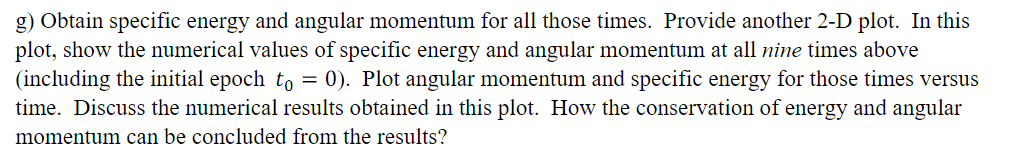

h_mag_QG_list = [];
specificE_QG_list =[];
for question_Gcount=1:length(t_list)

    %Use your OE's to get your r_vec and v_vec
    [r_vec_QG,v_vec_QG] = OEtoRV_silent(Semi_Major_axis_table(question_Gcount),Ecentricity_table(question_Gcount),true_annomoly_table(question_Gcount),inclination_table(question_Gcount),ascending_node_table(question_Gcount),arg_periapsis_table(question_Gcount));
    
    %calculate specific energy and angular momentum
    specificE_temp = RV_to_specific_energy(r_vec_QG,v_vec_QG);
    [~,h_mag_QG]= RV_to_h(r_vec_QG,v_vec_QG);

    %append the new values to the lists
    h_mag_QG_list = cat(1,h_mag_QG_list,h_mag_QG);
    specificE_QG_list = cat(1,specificE_QG_list,specificE_temp);
end

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

the specific energy ( ε ) is: -7.5023 km^2/s^2

h_vec: [47324.8151, -39706.8557, 30935.1707]  (km^2/s)
the specific angular moment (h) is: 69088.7639 (km^2/s)

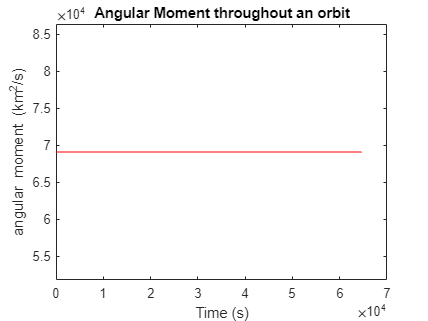


%plot to show angular moment and specific energy are constant
plot(t_list,h_mag_QG_list, 'r');
y_axis_limits = [h_mag*.75,h_mag*1.25];
ylim([min(y_axis_limits),max(y_axis_limits)]);
xlabel('Time (s)');
ylabel('angular moment (km^2/s)');
title('Angular Moment throughout an orbit');

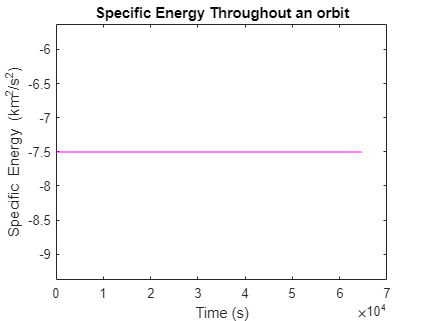



%this controls the specific energy plot
plot(t_list,specificE_QG_list, 'm');
y_axis_limits = [specificE*.75,specificE*1.25];
ylim([min(y_axis_limits),max(y_axis_limits)]);
xlabel('Time (s)');
ylabel('Specific Energy (km^2/s^2)');
title('Specific Energy Throughout an orbit');
hold off

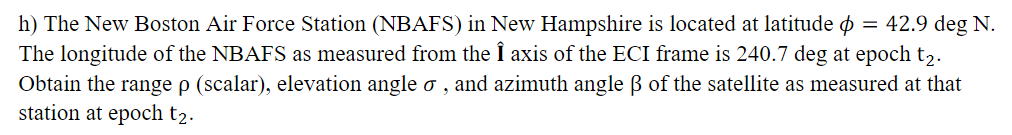

%define vars
phi = 42.9; %deg
lambda = 240.7; %deg

%{
test case: should output b=36, o=36.6, p=988
phi = 35; %deg
lambda = 40; %deg
r_vec_ECI = [3790.2499;3789.0065;4521.7964];
%}

% Note: r_site_SEZ assumes site is at sea level
r_site_SEZ = [0;0;6378]; %[km]

%get position vector of satelite at our values
l=3;
[r_vec_ECI,v_vec_ECI] = OEtoRV_silent(Semi_Major_axis_table(l),Ecentricity_table(l),true_annomoly_table(l),inclination_table(l),ascending_node_table(l),arg_periapsis_table(l));

% Transformation matrix from ECI to SEZ
ECItoSEZ = [sind(phi)*cosd(lambda),sind(phi)*sind(lambda),-cosd(phi);
            -sind(lambda),cosd(lambda),0; ...
            cosd(phi)*cosd(lambda),cosd(phi)*sind(lambda),sind(phi)];

%position vector of satelite in SEZ
r_vec_SEZ = ECItoSEZ  * r_vec_ECI;

%calculate range vector by subtracting site and satelite position vectors
p_vec_SEZ = r_vec_SEZ - r_site_SEZ;

p = norm(p_vec_SEZ);
o = asind(p_vec_SEZ(3)/p);
b = acosd(p_vec_SEZ(1)/(-p*cosd(o)));

%print values for azmuth angle, range, and elevation angle
fprintf('azmuth angle: %0.1f deg\n',b)

azmuth angle: 40.0 deg


fprintf('range: %0.1f km\n',p)

range: 39507.3 km


fprintf('elevation angle: %0.1f deg\n',o)

elevation angle: 36.4 deg


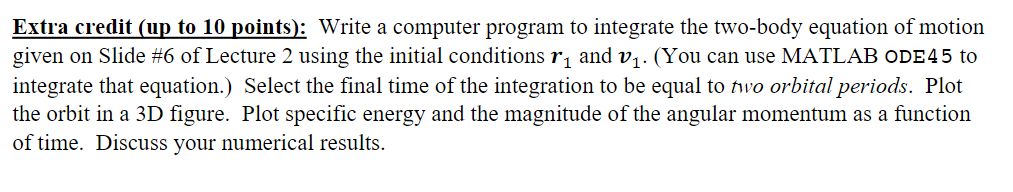

% Define gravitational constant and Earth radius
GMe = 398600; 
Re = 6378;  % km
r_vec0 = [-15865,13312,41357]; % km
v_vec0 = [-0.960,-1.1443,0]; % km/s

% Initial state vector [x, y, vx, vy]
X0 = cat(2,r_vec0,v_vec0);

% Define the time vctor
[a] = RVtoOE(r_vec0,v_vec0);

				RVtoOE
Semi Major Axis: 26564.9368 km 
Eccentricity: 0.7411 
Inclination: 63.4000 deg 
Longitude of Ascending Node: 50.0053 deg
Argument of Periapsis: 269.9972 deg
True Anomoly: 180.0007 deg


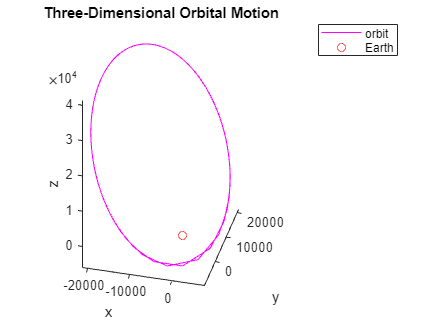

T = 2*pi*sqrt(a^3/GMe);
time = linspace(0,2*T);

% Preallocate the result matrix
answer = zeros(length(time), 6);

% Initialize the first row with the intial state
answer(1, :) = X0;

% Numerical integration of the derivatives
for i = 2:length(time)
    tspan = [time(i - 1), time(i)];
    X0 = answer(i - 1, :);
    [~, X] = ode45(@(t, X) deriv(t, X, GMe), tspan, X0);

    answer(i, :) = X(end, :);
end

% Create a 3D plot of the orbital motion
figure;
plot3(answer(:, 1), answer(:, 2), answer(:, 3), '-m');
hold on;
plot3(0, 0, 0, 'or');
axis equal;
xlabel('x');
ylabel('y');
zlabel('z');
title('Three-Dimensional Orbital Motion');
legend('orbit', 'Earth');
hold off

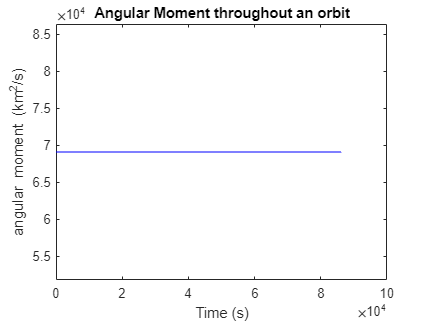


%WORK ON PLOTTING angular momentum
r_vec_EX = [answer(:,1),answer(:,2),answer(:,3)];
v_vec_EX = [answer(:,4),answer(:,5),answer(:,6)];

%Use for loop to go through and calculate the h_mag of each
%Use this for allocating RAM
h_list_table = zeros(length(time), 1);  

for h_list_num = 1:length(time)

    h_vec_tmp = cross(r_vec_EX(h_list_num,:),v_vec_EX(h_list_num,:));
    h_mag_tmp = norm(h_vec);
    h_list_table(h_list_num) = h_mag_tmp;
end

plot(time,h_list_table, 'b');
y_axis_limits = [h_mag_tmp*.75,h_mag_tmp*1.25];
ylim([min(y_axis_limits),max(y_axis_limits)]);
xlabel('Time (s)');
ylabel('angular moment (km^2/s)');
title('Angular Moment throughout an orbit');

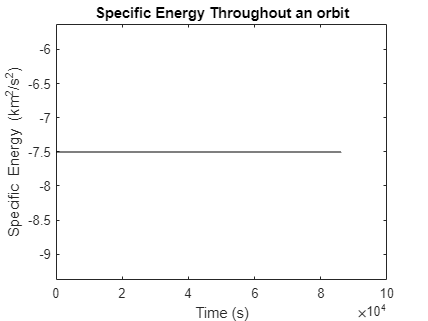



%Now repeat the process for specific energy
specE_list_table = zeros(length(time), 1);  

for specE_list_num = 1:length(time)
    specE_list_table(specE_list_num) = .5*(norm(v_vec_EX(specE_list_num,:)))^2 - mu_earth/norm(r_vec_EX(specE_list_num,:));;
end

%this controls the specific energy plot
plot(time,specE_list_table, 'k');
y_axis_limits = [specE_list_table(1)*.75,specE_list_table(1)*1.25];
ylim([min(y_axis_limits),max(y_axis_limits)]);
xlabel('Time (s)');
ylabel('Specific Energy (km^2/s^2)');
title('Specific Energy Throughout an orbit');
hold off

The function below takes a RV and find the angular momentum

function [h_vec,h_mag]= RV_to_h(r_vec,v_vec)
    
    
    h_vec = cross(r_vec,v_vec);
    h_mag = norm(h_vec);
    
    fprintf('h_vec: [%.4f, %.4f, %.4f]  (km^2/s)\n',  h_vec);
    fprintf('the specific angular moment (h) is: %.4f (km^2/s)',h_mag)
end



This is  a function that takes the r vector and velocity vector and returns the momentum and direction of you momentum

function specificE = RV_to_specific_energy(r_vec,v_vec)
    mu_earth = 398600;
    
    r_mag = norm(r_vec);
    v_mag = norm(v_vec);
    
    specificE = .5*(v_mag)^2 - mu_earth/r_mag;
    
    epsilon_symbol = char(949);
    fprintf('the specific energy ( %s ) is: %.4f km^2/s^2',epsilon_symbol,specificE)
end




This is a function to get RV's to OEs

function [r_vec,v_vec] = OEtoRV(a,e_mag,f,i,omegaUpper,omegalower)
    
    mu_earth = 398600;
    p = a*(1-e_mag^2);
    h = sqrt(p*mu_earth);
    r = p/(1+e_mag*cosd(f));
    r_PQW = [r*cosd(f); r*sind(f);0];
    v_PQW = [-mu_earth/h*sind(f); mu_earth/h*(e_mag+cosd(f)); 0];
    
    R_matrix = [
    cosd(omegaUpper) * cosd(omegalower) - sind(omegaUpper)*sind(omegalower)*cosd(i),-cosd(omegaUpper)*sind(omegalower) - sind(omegaUpper)*cosd(omegalower)*cosd(i), sind(omegaUpper)*sind(i);
    sind(omegaUpper)*cosd(omegalower) + cosd(omegaUpper)*sind(omegalower)*cosd(i), -sind(omegaUpper)*sind(omegalower) + cosd(omegaUpper)*cosd(omegalower)*cosd(i), -cosd(omegaUpper)*sind(i);
    sind(omegalower)*sind(i), cosd(omegalower)*sind(i), cosd(i)];

    %transform to ECI

    r_vec = R_matrix*r_PQW;
    v_vec = R_matrix*v_PQW;

    fprintf('Radius (r_vec): km\n');
    fprintf('%.5f km \n', r_vec);

    fprintf('\nVelocity (v_vec): km/s\n');
    fprintf('%.5f km/s \n', v_vec);

    r_str = sprintf('%.2fi + %.2fj', r_PQW(1), r_PQW(2));
    v_str = sprintf('%.2fi + %.2fj km/s', v_PQW(1), v_PQW(2));
    fprintf('\n Radius in PQW:\n%s km\n', r_str); fprintf('\nVelocity in PQW:\n%s km/s \n', v_str);


end


This is for OEtoRV:

% RVtoOE
function [a,e,f,i,Omega,w,e_Vec] = RVtoOE(r_Vec,v_Vec) 
    %define vars
    r_Hat = r_Vec / norm(r_Vec);
    mu = 398600;
    i_Hat = [1;0;0];
    j_Hat = [0;1;0];
    k_Hat = [0;0;1];
    
    %calculate semi major axis
    r = norm(r_Vec);
    epsilon = (0.5 * dot(v_Vec,v_Vec)) - (mu/r);
    a = -mu/(2*epsilon);
    
    %calculate eccentricity
    h_Vec = cross(r_Vec,v_Vec);
    e_Vec = (cross(v_Vec,h_Vec)/mu) - r_Hat;
    e = norm(e_Vec);
    e_Hat = e_Vec/e;
    
    %calculate inclination
    h_Hat = h_Vec/norm(h_Vec);
    i = acosd(dot(h_Hat,k_Hat));
    
    %equitorial and circular orbit
    if i ~= 180 && i ~= 0 && e==0 
        %calculate true longitude
        truelongitudecheck = dot(r_Hat,j_Hat);
        if truelongitudecheck >= 0
            L_true = acosd(dot(r_Hat,i_Hat));
        else
            L_true = 360 - acosd(r_Hat,i_Hat);
        end
        
        %print values
        fprintf('\t\t\t\tRVtoOE\n')
        fprintf('Semi Major Axis: %.4f km \n',a);
        fprintf('Eccentricity: %.4f \n',e);
        fprintf('Inclination: %.4f deg \n',i);
        fprintf('True longitude: %.4f deg\n',L_true);
    
    %equitorial orbit
    elseif i == 180 || i == 0
        %calculate true longitude of periapsis
        truelongitudePeriapsischeck = dot(e_Hat,j_Hat);
        if truelongitudePeriapsischeck >= 0
            w_true = acosd(dot(e_Hat,i_Hat));
        else
            w_true = 360 - acosd(e_Hat,i_Hat);
        end

        %calculate true anamoly
        trueAnomolyCheck = dot(r_Vec,v_Vec);
            if trueAnomolyCheck >= 0
                f = acosd(dot(e_Hat,r_Hat));
            else
                f = 360 - acosd(dot(e_Hat,r_Hat));
            end
        
        %print values
        fprintf('\t\t\t\tRVtoOE\n')
        fprintf('Semi Major Axis: %.4f km \n',a);
        fprintf('Eccentricity: %.4f \n',e);
        fprintf('Inclination: %.4f deg \n',i);
        fprintf('True longitude of Periapsis: %.4f deg\n',w_true);
        fprintf('True Anomoly: %.4f deg\n',f);

    %circular orbit
    elseif e==0
        %calculate longitude of the ascending node
        n_Hat = cross(k_Hat,h_Vec)/norm(cross(k_Hat,h_Vec));
        Omega = atan2d(n_Hat(2),n_Hat(1));

        %calculate argument of lattitude
        argumentOfLattitudeCheck = dot(r_Hat,k_Hat);
        if argumentOfLattitudeCheck >= 0
            theta = acosd(dot(n_Hat,r_Hat));
        else
            theta = 360 - acosd(dot(n_Hat,r_Hat));
        end

        %print values
        fprintf('\t\t\t\tRVtoOE\n')
        fprintf('Semi Major Axis: %.4f km \n',a);
        fprintf('Eccentricity: %.4f \n',e);
        fprintf('Inclination: %.4f deg \n',i);
        fprintf('Longitude of Ascending Node: %.4f deg\n',Omega);
        fprintf('Argument of Lattitude: %.4f deg\n',theta);

    else
        %calculate longitude of the ascending node
        n_Hat = cross(k_Hat,h_Vec)/norm(cross(k_Hat,h_Vec));
        Omega = atan2d(n_Hat(2),n_Hat(1));
        
        %calculate argument of periapsis
        periapsisCheck = dot(e_Hat,k_Hat);
            if periapsisCheck >= 0
                w = acosd(dot(n_Hat,e_Hat));
            else
                w = 360 - acosd(dot(n_Hat,e_Hat));
            end
        %calculate true anamoly
        trueAnomolyCheck = dot(r_Vec,v_Vec);
            if trueAnomolyCheck >= 0
                f = acosd(dot(e_Hat,r_Hat));
            else
                f = 360 - acosd(dot(e_Hat,r_Hat));
            end
        
        %print values
        fprintf('\t\t\t\tRVtoOE\n')
        fprintf('Semi Major Axis: %.4f km \n',a);
        fprintf('Eccentricity: %.4f \n',e);
        fprintf('Inclination: %.4f deg \n',i);
        fprintf('Longitude of Ascending Node: %.4f deg\n',Omega);
        fprintf('Argument of Periapsis: %.4f deg\n',w);
        fprintf('True Anomoly: %.4f deg\n',f);
    end
end

This uses the netwonian absom method to get eccentric enomoly and follows the equation shown below:

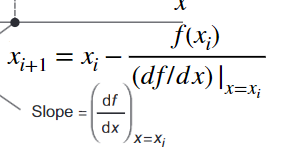

function [Eccentric_anomoly,true_annomaly] = newtonian_method(e_mag,M)

%This boolean is for an elliptical orbit
    if e_mag > 0 && e_mag < 1
        E = [];
        Newtonian_runs = 1;
        newtonian_error = 1;
        E(1) = M;

        while newtonian_error > 1e-5
            E(Newtonian_runs+1) = E(Newtonian_runs) - (E(Newtonian_runs)-e_mag*sin(E(Newtonian_runs))-M)/(1-e_mag*cos(E(Newtonian_runs)));
            newtonian_error = abs(E(Newtonian_runs)-E(Newtonian_runs+1));
            Newtonian_runs = Newtonian_runs + 1;
        end

    E_f = E(length(E));

    F_f = 0; %This is only for sake of easy of returning the function variable


    fprintf('Ecentricity annomaly [E2]: %.4f deg\n',E_f*(180/pi));
    %fprintf('Iterations of newtonian method: %.0f\n',Newtonian_runs)

    %Now calculate your true annomaly of elliptical orbit
    true_annomaly = 2*atan(sqrt((1+e_mag)/(1-e_mag))*tan(E_f/2));

    %This ensures you go CCW
    if true_annomaly < 0
            true_annomaly = true_annomaly + 2*pi;
    end
    fprintf('true annomaly [E2]: %.4f deg\n\n',true_annomaly*(180/pi));


    

%hyperbolic solution
    elseif e_mag > 1
        F = [];
        Newtonian_runs = 1;
        newtonian_error = 1;
        F(1) = M;

        while newtonian_error > 1e-5
            F(Newtonian_runs+1) = F(Newtonian_runs) - ((e_mag*sinh(F(Newtonian_runs)) - F(Newtonian_runs))/(e_mag*cosh(F(Newtonian_runs)) - Newtonian_runs));
            newtonian_error = abs(E(Newtonian_runs)-E(Newtonian_runs+1));
            Newtonian_runs = Newtonian_runs + 1;
        end

    F_f = F(Length(F));
    E_f = 0; %This is only for sake of easy of returning the function variable

    fprintf('The eccentricity anomaly [F]: %f deg\n', F_f*(180/pi));
    fprintf('Iterations: %.0f\n',Newtonian_runs)


    %Now calculate your true annomaly of hyperbolic
    true_annomaly = 2*atan(sqrt((1+e_mag)/(1-e_mag))*tanh(F_f/2));

       %This ensures you go CCW
        if true_annomaly < 0
            true_annomaly = true_annomaly + 2*pi;
        end
    fprintf('true annomaly [E2]: %.4f deg\n\n',true_annomaly*(180/pi));


    end

    %because of how the if statements are structured, only one of these
    %should be non-zero at any given moment.
    Eccentric_anomoly = E_f + F_f;
end


We can also validate Newtons method by using matlab VPA solve for ellitpical orbits, which is our current orbit

%THIS USES A DIFFERENT METHOD TO CALCLUATE E, this one only works for
%elliptical orbits and hyperbolic cases
function NOTNEWTON_method(e_mag,M)

    %this considers the elliptical case
    if e_mag > 0 && e_mag < 1
        syms E_test
    
        % Create the equation M = E - sin(E)
        equation = M == E_test - e_mag*sin(E_test);
    
        % Solve for E
        E_test = vpasolve(equation, E_test);
        fprintf("\n OTHER METHOD Eccentric anomoly: %.4f deg\n", E_test*180/pi)
    
        true_annomaly = 2*atan(sqrt((1+e_mag)/(1-e_mag))*tan(E_test/2));

       %This ensures you go CCW
        if true_annomaly < 0
            true_annomaly = true_annomaly + 2*pi;
        end
        fprintf('OTHER METHOD true annomaly [E2]: %.4f deg\n\n',true_annomaly*(180/pi));


    %This considers the hyperbolic case
    elseif e_mag > 1
        syms F_test
        equation = M == -F_test + e_mag*sinh(F_test);

        E_test = vpasolve(equation, F_test);
        fprintf("\n OTHER METHOD Eccentric anomoly: %.4f deg\n", E_test*180/pi)
    
        true_annomaly = 2*atan(sqrt((1+e_mag)/(1-e_mag))*tanh(E_test/2));
    
        %This ensures you go CCW
        if true_annomaly < 0
            true_annomaly = true_annomaly + 2*pi;
        end
        fprintf('OTHER METHOD true annomaly [E2]: %.4f deg\n\n',true_annomaly*(180/pi));

    else
        fprintf('INVALID orbit type for NOTNEWTON_method')
        return

    end
end

Below is the exact same function as OEtoRV, but this one has no fprintf, this is a solution to stopping the function from printing, but there are many other ways to do this

function [r_vec,v_vec] = OEtoRV_silent(a,e_mag,f,i,omegaUpper,omegalower)
    
    mu_earth = 398600;
    p = a*(1-e_mag^2);
    h = sqrt(p*mu_earth);
    r = p/(1+e_mag*cosd(f));
    r_PQW = [r*cosd(f); r*sind(f);0];
    v_PQW = [-mu_earth/h*sind(f); mu_earth/h*(e_mag+cosd(f)); 0];
    
    R_matrix = [
    cosd(omegaUpper) * cosd(omegalower) - sind(omegaUpper)*sind(omegalower)*cosd(i),-cosd(omegaUpper)*sind(omegalower) - sind(omegaUpper)*cosd(omegalower)*cosd(i), sind(omegaUpper)*sind(i);
    sind(omegaUpper)*cosd(omegalower) + cosd(omegaUpper)*sind(omegalower)*cosd(i), -sind(omegaUpper)*sind(omegalower) + cosd(omegaUpper)*cosd(omegalower)*cosd(i), -cosd(omegaUpper)*sind(i);
    sind(omegalower)*sind(i), cosd(omegalower)*sind(i), cosd(i)];

    %transform to ECI
    r_vec = R_matrix*r_PQW;
    v_vec = R_matrix*v_PQW;

end

This is the function that finds the derivatives

% Function to compute derivatives (three-dimensional two-body gravitational model)
function dX = deriv(t, X, GMe)
    r = X(1:3);
    v = X(4:6);
    R = norm(r);  % Distance from the center of the Earth
    acc = -GMe * r / R^3;  % Gravitational acceleration (two-body)
    dX = [v; acc];
end